# Final Project

clear; clc;

## Part A

clear; clc;

### Problem 1

f = @(x) x;
g = @(x) x.^2;
a = 0;
b = 2;
TOL = 2^-10;

[MS_val_f, err_val_f] = MilneSimpson(f, a, b, TOL);
[MS_val_g, err_val_g] = MilneSimpson(g, a, b, TOL);
int_val_f = integral(f, a, b);
int_val_g = integral(g, a, b);

The two functions chosen to validate the system were $f(x)=x$ and $g(x)=x^2$. Comparing the difference between the true integral value and the approximated integral value for $f$ gives

abs(MS_val_f - int_val_f)

ans =       2.22044604925031e-16


which is less than the tolerance of $2^{-10}$. Similarly, the difference between the true integral and the approximation can be compared for $g$, and this gives

abs(MS_val_g - int_val_g)

ans =      0


which is also less than the tolerance of $2^{-10}$.

### Problem 2


$$f(x)=x^{-3}$$


#### Subsection a.

f = @(x) x.^-3;

% Perform the first test
a = 2^-10;
b = 5;
TOL = 2^-100;

[int_val, err_val] = MilneSimpson(f, a, b, TOL);
[q, num_iter_quad] = quad(f, a, b, TOL);

real = integral(f, a, b);

abs(int_val(end) - real)

ans =       4.59491275250912e-07


abs(q - real)

ans =           19.1669236635207


Calculating the absolute value of the difference between the Milne-Simpson approximation and the real answer and doing the same for the quad() approximation shows that the Milne-Simpson approximation is more accurate by several orders of magnitude.

#### Subsection b.

% Change the tolerance
a = 2^-5;
b = 5;
TOL = 2^-10;

[int_val, err_val] = MilneSimpson(f, a, b, TOL);
[q, num_iter_quad] = quad(f, a, b, TOL);
real = integral(f, a, b);

abs(int_val(end) - real)

ans =       5.53548289872197e-05


abs(q - real)

ans =        0.00038081808708057


With a less restrictive tolerance, the Milne-Simpson approximation and the quad() are closer in value, though the Milne-Simpson approximation is still more accurate.

% Change the left endpoint
a = 2^-10;
b = 5;
TOL = 2^-10;

[int_val, err_val] = MilneSimpson(f, a, b, TOL);
[q, num_iter_quad] = quad(f, a, b, TOL);
real = integral(f, a, b);

abs(int_val(end) - real)

ans =       5.51588600501418e-05


abs(q - real)

ans =       0.000514953571837395


Changing the left endpoint does not affect the difference between Milne-Simpson and quad(). Milne-Simpson is still more accurate by an order of magnitude.


$$f(x)=x+sin(xlog(2x))$$


#### Subsection c.

f = @(x) x + sin(x.*log(2.*x));

% Perform the first test
a = 1;
b = 2^5;
TOL = 2^-40;

[int_val, err_val] = MilneSimpson(f, a, b, TOL);
[q, num_iter_quad] = quad(f, a, b, TOL);

int_val(end)

ans =           511.872315093939


q

q =           514.437499970453


abs(int_val(end) - q)

ans =           2.56518487651334


For this case, the difference between Milne-Simpson and quad() is small, though based on the previous tests it is likely that Milne-Simpson is the more accurate approximation.

#### Subsection d.

% Increase the right endpoint by a factor of 2
a = 1;
b = 2^5*2;
TOL = 2^-40;

[int_val, err_val] = MilneSimpson(f, a, b, TOL);
[q, num_iter_quad] = quad(f, a, b, TOL);

int_val(end)

ans =             2048.104849514


q

q =           2034.71244123767


abs(int_val(end) - q)

ans =           13.3924082763265


With a doubling of the right endpoint, the difference between the two methods increased by a factor of 10.

% Increase the right endpoint by a factor of 2 again
a = 1;
b = 2^5*4;
TOL = 2^-40;

[int_val, err_val] = MilneSimpson(f, a, b, TOL);
[q, num_iter_quad] = quad(f, a, b, TOL);

int_val(end)

ans =           8191.80474322974


q

q =           8158.27393169774


abs(int_val(end) - q)

ans =           33.5308115319949


This time, the difference only increased by a factor of 3. Thus it is reasonable to conclude that as the endpoint moves further and further right, the difference between the approximations will increase.


$$f(x)=\frac{cos(x)}{\sqrt{1+|x|}}$$


#### Subsection e.

% Perform the first iteration
f = @(x) cos(x)./sqrt(1+abs(x));
a = -15;
b = 15;
TOL = 2^-45;

[int_val, err_val] = MilneSimpson(f, a, b, TOL);
[q, num_iter_quad] = quad(f, a, b, TOL);
int_val(end)

ans =          0.800325731506307


q

q =          0.800325731506306


abs(int_val(end) - q)

ans =       1.66533453693773e-15


For a tolerance of $2^{-45}$, the error between Milne-Simpson and quad() is relatively small.

#### Subsection f.

% Cut tolerance by a factor of 2
TOL = 2^-46;

[int_val, err_val] = MilneSimpson(f, a, b, TOL);
[q, num_iter_quad] = quad(f, a, b, TOL);
int_val(end)

ans =          0.800325731506307


q

q =          0.800325731506306


abs(int_val(end) - q)

ans =       1.66533453693773e-15


Even after decreasing the tolerance by a factor of 2, the difference remains unchanged.

% Cut tolerance by a factor of 2 again
TOL = 2^-47;

[int_val, err_val] = MilneSimpson(f, a, b, TOL);
[q, num_iter_quad] = quad(f, a, b, TOL);
int_val(end)

ans =          0.800325731506305


q

q =          0.800325731506306


abs(int_val(end) - q)

ans =        7.7715611723761e-16


For a tolerance of $$2^{-47}$$, the difference between Milne-Simpson and quad() actually decreases by a factor of 10.

% Cut tolerance by another factor of 2
TOL = 2^-48;

[int_val, err_val] = MilneSimpson(f, a, b, TOL);
[q, num_iter_quad] = quad(f, a, b, TOL);

int_val(end)

ans =          0.800325731506305


q

q =          0.800326282311157


abs(int_val(end) - q)

ans =       5.50804852061937e-07


At a tolerance of $2^{-48}$, the difference between the methods begins to rise.

% Cut tolerance again
TOL = 2^-49;

[int_val, err_val] = MilneSimpson(f, a, b, TOL);
[q, num_iter_quad] = quad(f, a, b, TOL);

int_val(end)

ans =          0.800325731506305


q

q =          0.775530720279891


abs(int_val(end) - q)

ans =          0.024795011226414


As the tolerance continues to increase, the difference between the methods continues to grow.

% Cut tolerance again
TOL = 2^-50;

[int_val, err_val] = MilneSimpson(f, a, b, TOL);
[q, num_iter_quad] = quad(f, a, b, TOL);

int_val(end)

ans =          0.800325731506305


q

q =          0.775523556254478


abs(int_val(end) - q)

ans =         0.0248021752518267


Cutting from a tolerance of $2^{-49}$ to $2^{-50}$ does not change the difference between the approximations.

% Won't run
% Cut tolerance
% TOL = 2^-51;
% 
% [int_val, err_val] = MilneSimpson(f, a, b, TOL);
% [q, num_iter_quad] = quad(f, a, b, TOL);
% int_val(end)
% q
% abs(int_val(end) - q)

### Problem 3

It is clear from the comparison of the Milne-Simpson approximation and the quad() function to the actual value of the integral that the Milne-Simpson method is more accurate. Additionally, the test involving the last function show that when the tolerance becomes too tight, the quad() function is unable to converge on the solution accurately. The test with the second function show that over wider intervals, the error of quad() over Milnes-Simpson increases. Thus in all cases, Milne-Simpson is the more accurate method. This is likely due to the step where the average is taken of the two quadrature rules used, which are the closed formula with $n=2$ and the open formula with $n=2$.

## Part B

clear; clc

### Problem 1

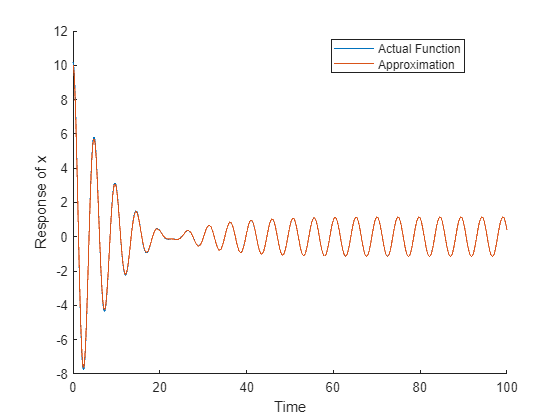

% Convert the second order ODE into a linear system of first order ODEs
f1 = @(t, y1, y2) y2;
f2 = @(t, y1, y2) (3*sin(13*t/10) - 17*y1 - 2*y2)/10;
a = 0;
b = 100;
h = 2^-6;
N = (b-a)/h;
alpha1 = 10;
alpha2 = 0;

[t_step, w_4step1, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);

x = @(t) (-780/677) .* cos((13.*t)/10) + ...
    (7550/667) .* exp(-t/10) .* cos((13.*t)/10) + ...
    (30/677) .* sin((13.*t)/10) + ...
    (7160/8801) .* exp(-t/10) .* sin((13.*t)/10);

% Plot the approximation and the solution
figure
hold on
plot(t_step, x(t_step))
plot(t_step, w_4step1)
xlabel("Time")
ylabel("Response of x")
legend("Actual Function", "Approximation", "Location", "best")
hold off

By plotting the approximation over the actual solution, it is shown that the code correctly implements the fourth order Adams-Bashforth predictor-corrector method.

### Problem 2

#### Subsection a.

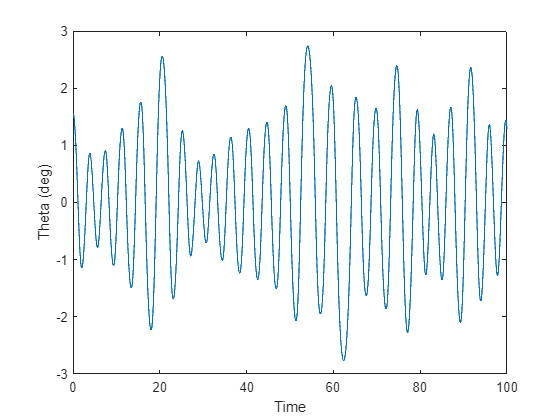

% Convert the pendulum equation into two first order ODEs and run the case
% where gamma is 3
gamma = 3;
f1 = @(t, y1, y2) y2;
f2 = @(t, y1, y2) -(0.5*y2 + (32.174 - gamma^2*sin(gamma*t))*sin(y1))/10;
a = 0;
b = 100;
h = 2^-10;
N = (b-a)/h;
alpha1 = pi/2;
alpha2 = 0;
[t_step, w_4step1, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);
plot(t_step, w_4step1)
xlabel("Time")
ylabel("Theta (deg)")

For the case where gamma is 3, the system appears to be marginally stable, with the pendulum oscillating consistently with slight variations in $\theta
$ due to the motion of the block.

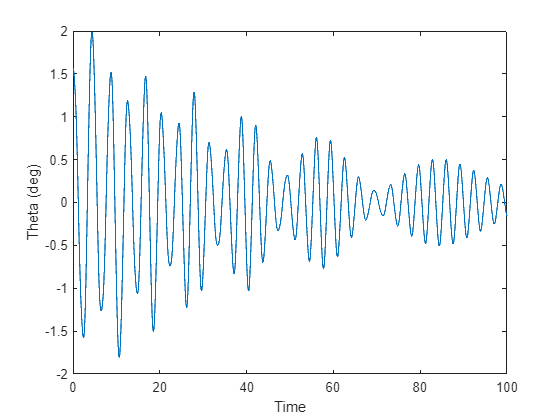

% Convert the pendulum equation into two first order ODEs and run the case
% where gamma is 4
gamma = 4;
f1 = @(t, y1, y2) y2;
f2 = @(t, y1, y2) -(0.5*y2 + (32.174 - gamma^2*sin(gamma*t))*sin(y1))/10;
a = 0;
b = 100;
h = 2^-10;
N = (b-a)/h;
alpha1 = pi/2;
alpha2 = 0;
[t_step, w_4step1, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);
plot(t_step, w_4step1)
xlabel("Time")
ylabel("Theta (deg)")

For the case where gamma is 4, the motion of the pendulum appears to be stable, with $\theta
$ relatively consistently decreasing in magnitude until the stop time. The motion of the block is still apparent in the "bubbles" that form, particularly past t=40;

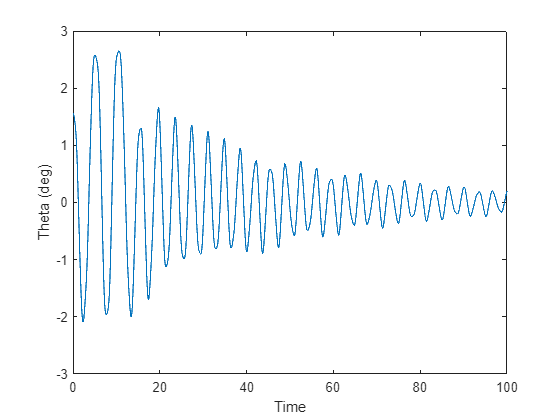

% Convert the pendulum equation into two first order ODEs and run the case
% where gamma is 5
gamma = 5;
f1 = @(t, y1, y2) y2;
f2 = @(t, y1, y2) -(0.5*y2 + (32.174 - gamma^2*sin(gamma*t))*sin(y1))/10;
a = 0;
b = 100;
h = 2^-10;
N = (b-a)/h;
alpha1 = pi/2;
alpha2 = 0;
[t_step, w_4step1, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);
plot(t_step, w_4step1)
xlabel("Time")
ylabel("Theta (deg)")

For the case where gamma is 5, the motion is almost certainly stable, with $\theta$ quickly decreasing with time. Notably, the motion of the block is not readily apparent in this situation, as there are no larger oscillations within the back-and-forth motion of the pendulum.

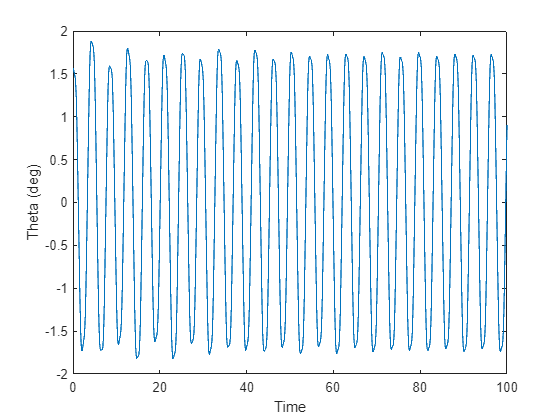

% Convert the pendulum equation into two first order ODEs and run the case
% where gamma is 6
gamma = 6;
f1 = @(t, y1, y2) y2;
f2 = @(t, y1, y2) -(0.5*y2 + (32.174 - gamma^2*sin(gamma*t))*sin(y1))/10;
a = 0;
b = 100;
h = 2^-10;
N = (b-a)/h;
alpha1 = pi/2;
alpha2 = 0;
[t_step, w_4step1, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);
plot(t_step, w_4step1)
xlabel("Time")
ylabel("Theta (deg)")

Once gamma hits 6, the system returns to marginal stability. Likely the block is now oscillating too fast to significantly affect the swinging of the pendulum.

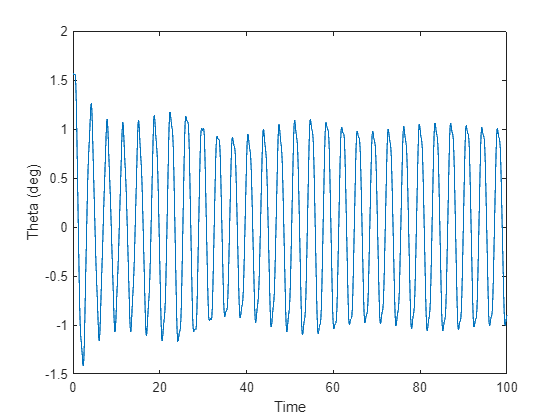

% Convert the pendulum equation into two first order ODEs and run the case
% where gamma is 7
gamma = 7;
f1 = @(t, y1, y2) y2;
f2 = @(t, y1, y2) -(0.5*y2 + (32.174 - gamma^2*sin(gamma*t))*sin(y1))/10;
a = 0;
b = 100;
h = 2^-10;
N = (b-a)/h;
alpha1 = pi/2;
alpha2 = 0;
[t_step, w_4step1, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);
plot(t_step, w_4step1)
xlabel("Time")
ylabel("Theta (deg)")

Similar to the case where gamma was 6, the case where gamma is 7 exhibits marginal stability, with the motion of the block just visible in the plot.

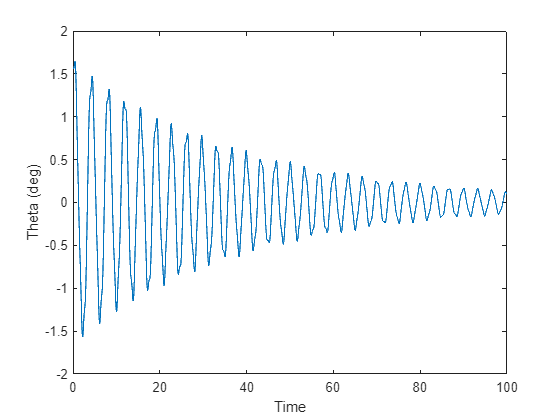

% Convert the pendulum equation into two first order ODEs and run the case
% where gamma is 8
gamma = 8;
f1 = @(t, y1, y2) y2;
f2 = @(t, y1, y2) -(0.5*y2 + (32.174 - gamma^2*sin(gamma*t))*sin(y1))/10;
a = 0;
b = 100;
h = 2^-10;
N = (b-a)/h;
alpha1 = pi/2;
alpha2 = 0;
[t_step, w_4step1, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);
plot(t_step, w_4step1)
xlabel("Time")
ylabel("Theta (deg)")

For the case where gamma is 8, the system returns to true stability, likely because the block is now oscillating at a frequency which is a harmonic of the first frequency that caused this stable behavior in the motion of the pendulum.

#### Subsection b.

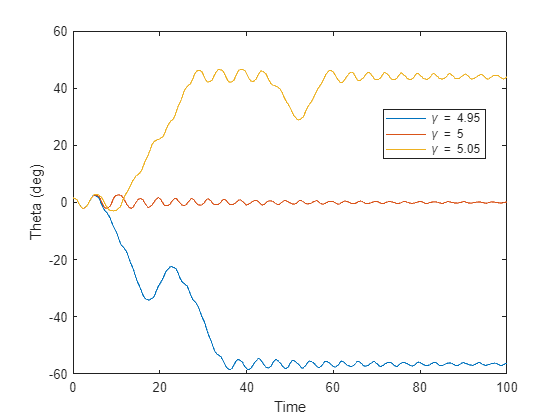

% Investigate gammas close to 5
gamma = 4.95;
f1 = @(t, y1, y2) y2;
f2 = @(t, y1, y2) -(0.5*y2 + (32.174 - gamma^2*sin(gamma*t))*sin(y1))/10;
a = 0;
b = 100;
h = 2^-15;
N = (b-a)/h;
alpha1 = pi/2;
alpha2 = 0;
[t_step_a, w_4step1_a, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);

gamma = 5;
f1 = @(t, y1, y2) y2;
f2 = @(t, y1, y2) -(0.5*y2 + (32.174 - gamma^2*sin(gamma*t))*sin(y1))/10;
a = 0;
b = 100;
h = 2^-15;
N = (b-a)/h;
alpha1 = pi/2;
alpha2 = 0;
[t_step_b, w_4step1_b, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);

gamma = 5.05;
f1 = @(t, y1, y2) y2;
f2 = @(t, y1, y2) -(0.5*y2 + (32.174 - gamma^2*sin(gamma*t))*sin(y1))/10;
a = 0;
b = 100;
h = 2^-15;
N = (b-a)/h;
alpha1 = pi/2;
alpha2 = 0;
[t_step_c, w_4step1_c, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);

plot(t_step_a, w_4step1_a, ...
    t_step_b, w_4step1_b, ...
    t_step_c, w_4step1_c)
xlabel("Time")
ylabel("Theta (deg)")
legend("\gamma = 4.95", "\gamma = 5", "\gamma = 5.05", "Location", "best")

If gamma is 5, then the graph is stable, and $\theta$ approaches zero. If gamma is slightly less than 5, the response tends towards a large negative $\theta$. If gamma is slightly greater than 5, the response tends towards a large positive $\theta$. This behavior likely indicates that $\gamma=5$ represents an unstable equilibrium point, where a value of 5 produces true stability but small deviations around 5 produce a system that drives away from zero.

### Problem 3

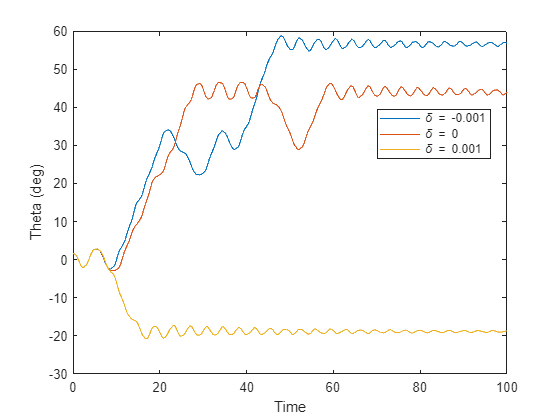

% Investigate small deviations to the initial conditions
gamma = 5.05;
f1 = @(t, y1, y2) y2;
f2 = @(t, y1, y2) -(0.5*y2 + (32.174 - gamma^2*sin(gamma*t))*sin(y1))/10;
a = 0;
b = 100;
h = 2^-15;
N = (b-a)/h;
alpha2 = 0;

alpha1 = pi/2 - 0.001;
[t_step_a, w_4step1_a, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);

alpha1 = pi/2;
[t_step_b, w_4step1_b, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);

alpha1 = pi/2 + 0.001;
[t_step_c, w_4step1_c, w_4step2] = AdamBashforthPredictorMethod2Ord(f1, f2, a, b, N, alpha1, alpha2);

plot(t_step_a, w_4step1_a, ...
    t_step_b, w_4step1_b, ...
    t_step_c, w_4step1_c)
xlabel("Time")
ylabel("Theta (deg)")
legend("\delta = -0.001", "\delta = 0", "\delta = 0.001", "Location", "best")

At a gamma value of 5.05, very small changes to the initial conditions produce very different responses. If the delta value is slightly negative or zero, then the response will tend towards a large positive value of $\theta$, though the actual response differs significantly. However, if the delta value is slightly positive, then the response will tend towards a large negative value of $\theta
$, thereby exhibiting the opposite of the expected behavior. These results further support the hypothesis that $\gamma=5$ is an unstable equilibrium point, where small deviations from it produce wildly different results.

## Part C

clear; clc;

### Problem 1

#### Subsections a.-h.

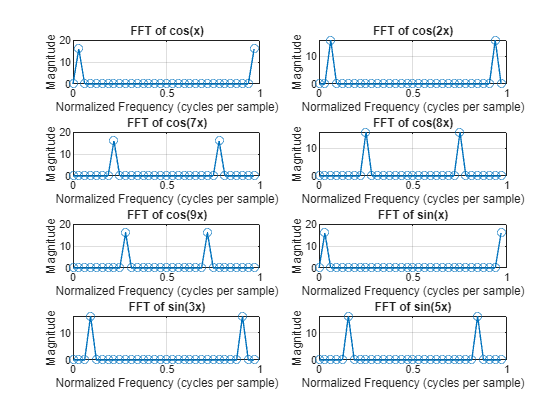

N = 32;
x = zeros(1, N);

% Define x vector
for i = 0:N-1
    x(i+1) = -pi + i*pi/16;
end

% Plotting tool
function_names = {'cos(x)', 'cos(2x)', 'cos(7x)', ...
                  'cos(8x)', 'cos(9x)', 'sin(x)', ...
                  'sin(3x)', 'sin(5x)'};

% Take the fft() of each function
y = @(x) cos(x);
fft_ans(1,:) = fft(y(x));
y = @(x) cos(2*x);
fft_ans(2,:) = fft(y(x));
y = @(x) cos(7*x);
fft_ans(3,:) = fft(y(x));
y = @(x) cos(8*x);
fft_ans(4,:) = fft(y(x));
y = @(x) cos(9*x);
fft_ans(5,:) = fft(y(x));
y = @(x) sin(x);
fft_ans(6,:) = fft(y(x));
y = @(x) sin(3*x);
fft_ans(7,:) = fft(y(x));
y = @(x) sin(5*x);
fft_ans(8,:) = fft(y(x));

figure
hold on
for i = 1:8
    Y = fft_ans(i,:);
    freq = (0:N-1)/N;

    subplot(4, 2, i); % Arrange plots in a 4x2 grid
    plot(freq, abs(Y), '-o');  % Magnitude spectrum
    title(['FFT of ', function_names{i}]);
    xlabel('Normalized Frequency (cycles per sample)');
    ylabel('Magnitude');
    grid on;
end
hold off

The fast fourier transforms of each of the functions of the given data set are shown above relative to a normalized frequency. If a sampling frequency were given, simply multiplying the normalized frequencies by the sampling frequency would give the response at that frequency for some system.

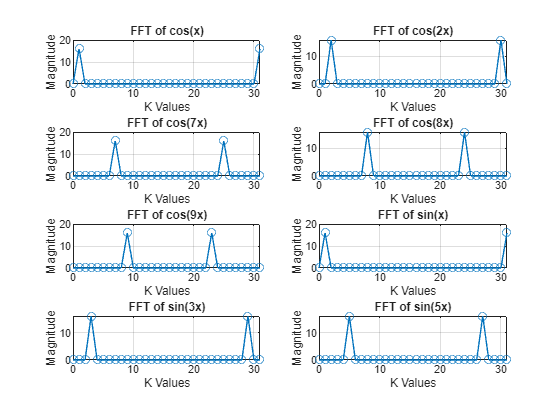

figure
hold on
for i = 1:8
    Y = fft_ans(i,:);

    subplot(4, 2, i); % Arrange plots in a 4x2 grid
    plot(0:N-1, abs(Y), '-o');  % Magnitude spectrum
    title(['FFT of ', function_names{i}]);
    xlabel('K Values');
    ylabel('Magnitude');
    grid on;
end
hold off

These are the same graphs, but plotted against the k-values instead of normalized frequencies. Note that the peaks occur at the coefficients of the arguments of x in the trig functions and at the symmetric k value representing the negative of the same frequency.

### Problem 2

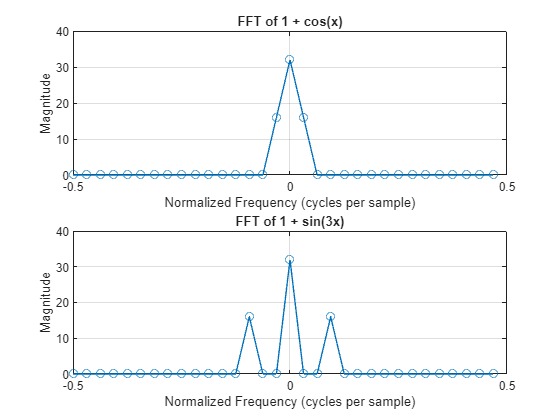

function_names_shift = {'1 + cos(x)', '1 + sin(3x)'};

y_shift = @(x) 1 + cos(x);
fft_shift_ans(1, :) = fftshift(fft(y_shift(x)), 2);
y_shift = @(x) 1 + sin(3*x);
fft_shift_ans(2, :) = fftshift(fft(y_shift(x)), 2);

figure
hold on
for i = 1:2
    Y = fft_shift_ans(i,:);
    freq = (-N/2:N/2-1)/N;

    subplot(2, 1, i); % Arrange plots in a 4x2 grid
    plot(freq, abs(Y), '-o');  % Magnitude spectrum
    title(['FFT of ', function_names_shift{i}]);
    xlabel('Normalized Frequency (cycles per sample)');
    ylabel('Magnitude');
    grid on;
end
hold off

For a shifted fast fourier transform, the zero-frequency component is shifted to the center of the plot. Note that because there is an added constant for these functions (and thus there is a zero-frequency component), there is a spike in the center representing the zero-frequency response. Note that the magnitude of each side peak is half of the middle peak (or that the magnitude of the two side peaks adds to the magnitude of the middle peak).

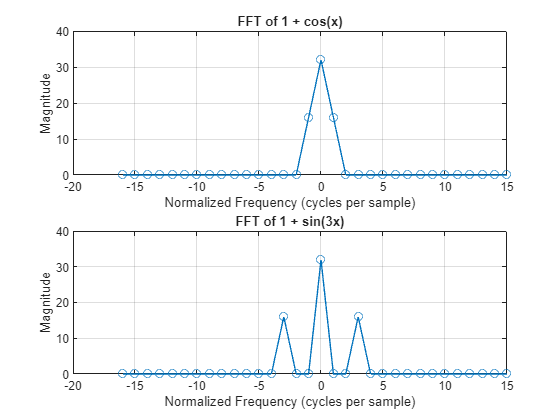


figure
hold on
for i = 1:2
    Y = fft_shift_ans(i,:);

    subplot(2, 1, i); % Arrange plots in a 4x2 grid
    plot((-N/2:N/2-1), abs(Y), '-o');  % Magnitude spectrum
    title(['FFT of ', function_names_shift{i}]);
    xlabel('Normalized Frequency (cycles per sample)');
    ylabel('Magnitude');
    grid on;
end
hold off

In the k-value version of these plots, it is clear that, as before, the outside peaks occur at the value of k (and its symmetric twin) that is the coefficient of the argument of the trig function. Because these outside peaks for $f(x)=1+cos(x)$ are located at a k value of 1 and these function do have a zero-frequency component, its shifted fft plot appears as one large peak. 

### Problem 3

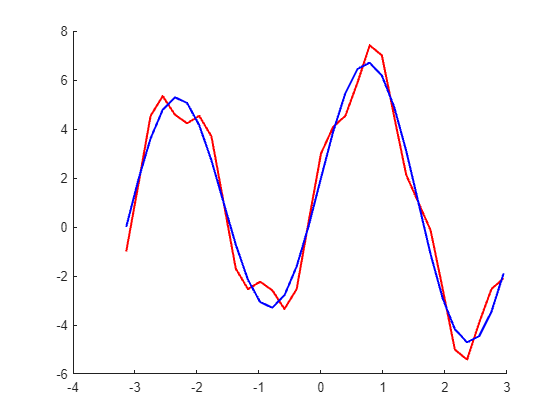

N = 32;
x = zeros(1, N);

for i = 0:N-1
    x(i+1) = -pi + i*pi/(N/2);
end

f = @(x) 1 + cos(x) + 5*sin(2*x) + cos(7*x);
fft_ans = fft(f(x));
fft_ans([4:end-2]) = 0; %Set higher frequencies to zero, effectively ignoring them.
inv_fft = ifft(fft_ans);

figure
hold on
plot(x, f(x), 'r-', 'LineWidth', 1.5)
plot(x, inv_fft, 'b-', 'LineWidth', 1.5)

The red line represents the original function, while the blue line represents the filtered function. Note that once the high frequencies are removed, the function becomes smoother as much of the noise has been nullified. In this case, taking only the low frequencies still captured the true pattern of the original function, though this may not always be the case. It is possible to filter out some of the information of the function in an attempt to minimize noise and smoothe the plot.

### Problem 4

N = 16;
x = zeros(1, N);

for i = 0:N-1
    x(i+1) = -pi + i*pi/(N/2);
end

f = @(x) x.^2.*cos(x);
fft_ans = fft(f(x));
c = fft_ans(1)/N; % Compute the zero frequency component

syms t
g(t) = c + (t - t);
for i = 1:8
    % Implement 8.29 from the text book
    g(t) = g + (-1)^i*(1/8)*real(fft_ans(i+1))*cos(i*t) + (-1)^i*(1/8)*imag(fft_ans(i+1))*sin(i*t);
end

g

$$g(t) = 0.6807\,\cos\left(3\,t\right)-2.2757\,\cos\left(2\,t\right)-0.3613\,\cos\left(4\,t\right)+0.2445\,\cos\left(5\,t\right)-0.1917\,\cos\left(6\,t\right)+0.1674\,\cos\left(7\,t\right)-0.1603\,\cos\left(8\,t\right)+2.3551e-16\,\sin\left(2\,t\right)-5.5511e-16\,\sin\left(3\,t\right)+7.7716e-16\,\sin\left(4\,t\right)-5.5511e-16\,\sin\left(5\,t\right)+2.3551e-16\,\sin\left(6\,t\right)+2.7756e-17\,\sin\left(7\,t\right)+3.8421\,\cos\left(t\right)+2.7756e-17\,\sin\left(t\right)-2.0259$$

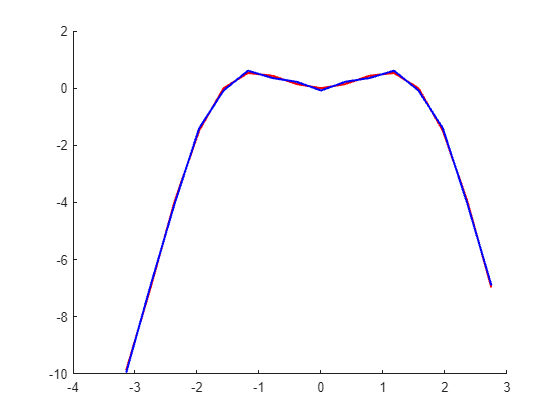

figure
hold on
plot(x, f(x), 'r-', 'LineWidth', 1.5)
plot(x, g(x), 'b-', 'LineWidth', 1.5)

The red line represents the original function, while the blue line represents the trigonometric polynomial approximation. For this scenario, the error is quite small.

## Part D

clear; clc;

### Problem 1

A = [1 2 1 3;
    2 1 2 3;
    0 1 1 1;
    1 1 3 1];
x = ones(4,1);
TOL = 2^-20;
[lambda, eig_vec, err] = powerEig(A, x, TOL);
format longg
[[1:length(lambda)]' lambda', eig_vec', err']

ans =                          1                         7                     0.875                         1                     0.375                      0.75                     0.625
                         2                      5.75         0.956521739130435                         1         0.369565217391304         0.652173913043478        0.0978260869565217
                         3          5.60869565217391         0.941860465116279                         1          0.36046511627907         0.662790697674419        0.0146612740141557
                         4          5.59302325581395         0.945945945945946                         1         0.361746361746362         0.659043659043659       0.00408548082966675
                         5          5.59251559251559         0.944981412639405                         1         0.361338289962825         0.659851301115242       0.00096453330654056
                         6          5.59219330855019         0.945223692082696 

The first column gives the iteration, the second gives the eigenvalue, the third, fourth, and fifth give the eigenvector, and the last gives the error. For this matrix, the eigenvalue calculated was $\lambda=5.592$, the eigenvector $\mathbf{x} = \pmatrix{0.945 \cr 1 \cr 0.361 \cr 0.660}$, and the error $Err=8.95e-7$

### Problem 2

[V, D] = eig(A)

V =         -0.602725474640944        -0.725169292711685        -0.712802686555381        -0.442050959117293
        -0.637685919925194        -0.492780876340196        0.0247872760223864        -0.597337019839681
        -0.230467072976087         0.354707306106896        -0.280333723138767       -0.0406054696385587
        -0.420670414959079         0.324775663829376         0.642425812571365         0.667930108699976


D =           5.59222361449477                         0                         0                         0
                         0          0.52635536506206                         0                         0
                         0                         0         -1.38006716110811                         0
                         0                         0                         0        -0.738511818448724


V(:, 1)./eig_vec(:,end)

ans =         -0.637685800446275
        -0.637685919925194
         -0.63768579711249
        -0.637686065517774


The eigenvalue matches, and the eigenvector is scaled by a factor of -0.6377.

### Problem 3

When finding the infinity norm of the vector x in the power method, the function assumes that there is only one dominant eigenvalue and thus there will only be one max. If there are 2, the function has no way to account for which eigenvalue it is driving towards and thus the method will not converge.

### Problem 4


$$det(\mathbf{A}-\lambda I)=0$$



$$det((\mathbf{A}+cI)-\lambda I)=0$$



$$det(\mathbf{A}+(c-\lambda)I)=0$$


Thus where $\lambda$ was an eigenvalue, so too is $\lambda+c
$ for $\mathbf{A}+cI$because $(c-(\lambda+c))=-\lambda$, which matches $det(\mathbf{A}-\lambda I)=0$. Because $\lambda$ remains unchanged, so does $\mathbf{x}$.

### Problem 5

A = [-1 -1 0; 0 0 1; 0 0 1];
x = ones(3,1);
TOL = 2^-50;
[lambda, eig_vec, err] = powerEig(A + 2*eye(3), x, TOL);
lambda(end) - 2

ans =      1


eig_vec(:,end)

ans =                       -0.5
                         1
                         1


This is the first dominant eigenvalue and its corresponding eigenvector.

[lambda, eig_vec, err] = powerEig(A - 2*eye(3), x, TOL);
lambda(end) + 2

ans =                         -1


eig_vec(:,end)

ans =                          1
      3.59773018490286e-16
      3.59773018490286e-16


This is the second dominant eigenvalue and its corresponding eigenvector

[V, D] = eig(A)

V =                          1        -0.707106781186547        -0.333333333333333
                         0         0.707106781186547         0.666666666666667
                         0                         0         0.666666666666667


D =     -1     0     0
     0     0     0
     0     0     1


Note that they match eig(), though the eigenvectors of eig() are scaled differently.